%% Optimized MATLAB Code for Skin Cancer Detection with SVM and Live Image Capture
% Faster Execution with Optimized Feature Extraction (No PCA)

close all; clear; clc;

disp('Welcome to the Skin Cancer Detection System!');

Welcome to the Skin Cancer Detection System!



%% Step 1: Load the Dataset

% Select ground truth file
[excelFile, excelPath] = uigetfile({'*.xlsx;*.csv'}, 'Select the Ground Truth File');
if isequal(excelFile, 0)
    error('No ground truth file selected.');
end
fullExcelPath = fullfile(excelPath, excelFile);
disp(['Ground truth file selected: ', fullExcelPath]);

Ground truth file selected: C:\Users\Himabala\OneDrive\Documents\GroundTruth.xlsx



% Select image and mask folders
imageFolder = uigetdir('', 'Select Folder with Images');
maskFolder = uigetdir('', 'Select Folder with Masks');
if isempty(imageFolder) || isempty(maskFolder)
    error('Folders not selected correctly.');
end

disp(['Selected image folder: ', imageFolder]);

Selected image folder: C:\Users\Himabala\OneDrive\Desktop\SkinCancerDetection\images


disp(['Selected mask folder: ', maskFolder]);

Selected mask folder: C:\Users\Himabala\OneDrive\Desktop\SkinCancerDetection\masks



% Load metadata
metadata = readtable(fullExcelPath);
imageIDCol = 'image';
classCols = metadata.Properties.VariableNames(2:end);

% Get list of image files
imageFiles = dir(fullfile(imageFolder, '*.jpg'));
maskFiles = dir(fullfile(maskFolder, '*.png'));
disp(['Number of images found: ', num2str(length(imageFiles))]);

Number of images found: 10015


disp(['Number of masks found: ', num2str(length(maskFiles))]);

Number of masks found: 10015



%% Step 2: Feature Extraction (No PCA)

disp('Extracting features...');

Extracting features...


features = [];
labels = [];

for i = 1:min(height(metadata), length(imageFiles))
    img = imread(fullfile(imageFiles(i).folder, imageFiles(i).name));
    
    % Convert to grayscale if needed
    if size(img, 3) == 3
        img = rgb2gray(img);
    end
    img = imresize(img, [64 64]);
    
    % Extract HOG features with optimized settings
    featureVector = extractHOGFeatures(img, 'CellSize', [16 16]);
    
    features = [features; featureVector];
    labels = [labels; metadata{i, 2}];
    
    if mod(i, 10) == 0
        fprintf('Processed %d images...\n', i);
    end
end

Processed 10 images...
Processed 20 images...
Processed 30 images...
Processed 40 images...
Processed 50 images...
Processed 60 images...
Processed 70 images...
Processed 80 images...
Processed 90 images...
Processed 100 images...
Processed 110 images...
Processed 120 images...
Processed 130 images...
Processed 140 images...
Processed 150 images...
Processed 160 images...
Processed 170 images...
Processed 180 images...
Processed 190 images...
Processed 200 images...
Processed 210 images...
Processed 220 images...
Processed 230 images...
Processed 240 images...
Processed 250 images...
Processed 260 images...
Processed 270 images...
Processed 280 images...
Processed 290 images...
Processed 300 images...
Processed 310 images...
Processed 320 images...
Processed 330 images...
Processed 340 images...
Processed 350 images...
Processed 360 images...
Processed 370 images...
Processed 380 images...
Processed 390 images...
Processed 400 images...
Processed 410 images...
Processed 420 images...
P


labels = categorical(labels);
save('Optimized_Features.mat', 'features');
save('Optimized_Labels.mat', 'labels');
disp('Feature extraction completed and saved.');

Feature extraction completed and saved.



%% Step 3: Train SVM Model

disp('Training SVM Model...');

Training SVM Model...


cv = cvpartition(size(features, 1), 'HoldOut', 0.2);
trainFeatures = features(training(cv), :);
trainLabels = labels(training(cv));
testFeatures = features(test(cv), :);
testLabels = labels(test(cv));

svmModel = fitcecoc(trainFeatures, trainLabels);
save('Optimized_SVM_Model.mat', 'svmModel');
disp('SVM model trained and saved!');

SVM model trained and saved!



% Evaluate model
predictedLabels = predict(svmModel, testFeatures);
accuracy = sum(predictedLabels == testLabels) / length(testLabels) * 100;
disp(['Model Accuracy: ', num2str(accuracy), '%']);

Model Accuracy: 89.0165%



% Calculate performance metrics
confMatrix = confusionmat(testLabels, predictedLabels);

precision = diag(confMatrix) ./ sum(confMatrix, 2);
recall = diag(confMatrix) ./ sum(confMatrix, 1)';
f1Score = 2 * (precision .* recall) ./ (precision + recall);

% Handle NaNs for F1-Score
precision(isnan(precision)) = 0;
recall(isnan(recall)) = 0;
f1Score(isnan(f1Score)) = 0;

% Display metrics
disp(['Precision: ', num2str(mean(precision) * 100), '%']);

Precision: 50%


disp(['Recall: ', num2str(mean(recall) * 100), '%']);

Recall: 44.5082%


disp(['F1-Score: ', num2str(mean(f1Score) * 100), '%']);

F1-Score: 47.0946%


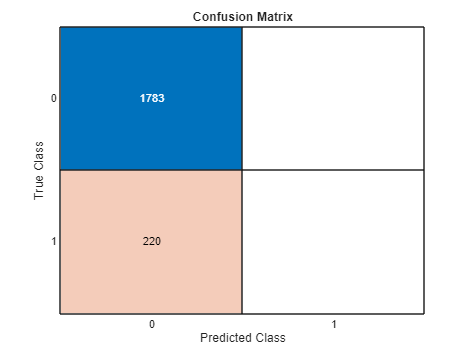


figure; confusionchart(testLabels, predictedLabels); title('Confusion Matrix');

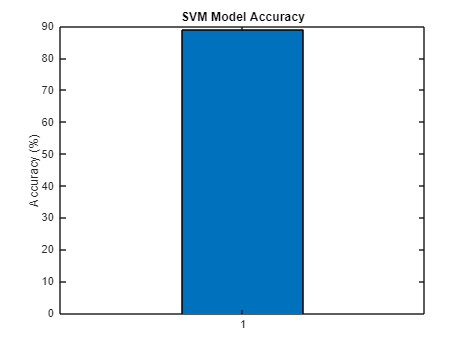

figure; bar(accuracy); title('SVM Model Accuracy'); ylabel('Accuracy (%)');


%% Step 4: Live Image Prediction from Webcam (No PCA)

disp('Capturing Live Image from Webcam...');

Capturing Live Image from Webcam...


camera = webcam;
pause(3); % Allow some time for camera to adjust
img = snapshot(camera);
clear camera; % Release the camera

disp('Image Captured Successfully!');

Image Captured Successfully!


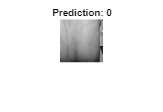


% Preprocess the image
img = imresize(img, [64 64]);
if size(img, 3) == 3
    img = rgb2gray(img);
end

% Extract HOG features
featureVector = extractHOGFeatures(img, 'CellSize', [16 16]);
featureVector = featureVector(:)'; % Ensure row vector

% Predict with SVM model
load('Optimized_SVM_Model.mat', 'svmModel');
predictedLabel = predict(svmModel, featureVector);

% Display the result
figure; imshow(img); title(['Prediction: ', char(predictedLabel)]);

disp(['The given skin image is classified as: ', char(predictedLabel)]);

The given skin image is classified as: 0
